# Training 

Learn the noise probability distribution from the relative distance and velocity readings. 

Load the mat file

file_path = 'D:\mukul\Desktop\Unimelb\Masters\exchange\optimal control\DNN_Tube_MPC\noise_dnn_train\sensor_data.mat';
data = load(file_path)

data = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]

sensor_rel_distance = data.data{1}.Values.Data;
sensor_rel_velocity = data.data{2}.Values.Data;
ground_truth_rel_distance = data.data{3}.Values.Data;
ground_truth_rel_velocity = data.data{4}.Values.Data;


### Noise estimation 

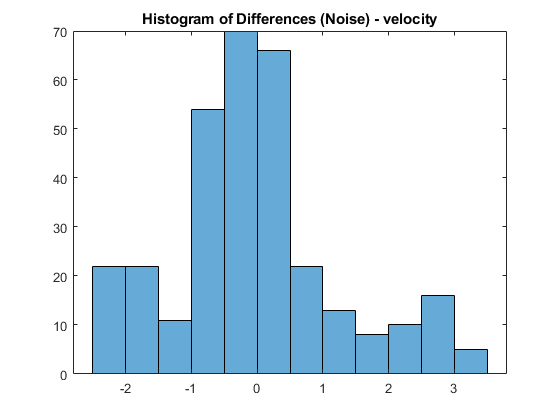

Parameters of fitted Gaussian distribution for noise:
  NormalDistribution

  Normal distribution
       mu = -0.0513304   [-0.191677, 0.0890165]
    sigma =    1.27407   [1.18228, 1.38143]



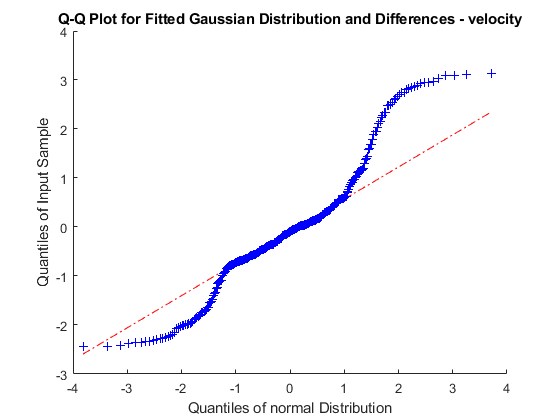

noise_data_vel = perform_qq_test(ground_truth_rel_velocity, sensor_rel_velocity, 'velocity');

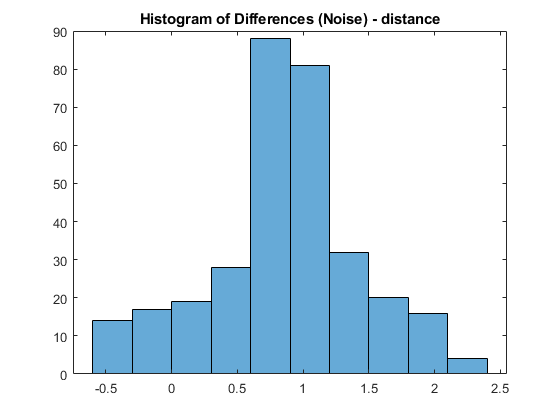

Parameters of fitted Gaussian distribution for noise:
  NormalDistribution

  Normal distribution
       mu = 0.861023   [0.79649, 0.925557]
    sigma = 0.585838   [0.543632, 0.635205]



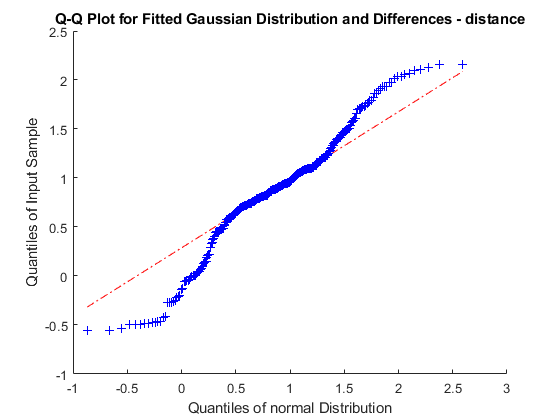

noise_data_dist = perform_qq_test(ground_truth_rel_distance, sensor_rel_distance, 'distance');

QQ Plot Interpretation

Figure  depicts a quantile-quantile (QQ) plot, a visual tool for comparing the quantiles of two distributions. In this instance, the QQ plot compares the quantiles of a fitted Gaussian distribution to the quantiles of an input sample. The goal is to assess the normality of the input sample by examining how closely its quantiles align with those of a normal distribution.

Ideally, if the input sample's quantiles perfectly align with the quantiles of the fitted Gaussian distribution, the points on the QQ plot would fall along a straight line. This would indicate that the input sample follows a normal distribution. However, in this case, the points deviate slightly from the straight line, particularly at the tails of the distribution.

The deviations at the lower tail suggest that the input sample has a slightly heavier tail than the fitted Gaussian distribution. This means that there are more extreme values (outliers) in the lower tail of the input sample than would be expected in a normal distribution. Conversely, the deviations at the upper tail suggest that the input sample has a slightly lighter tail than the fitted Gaussian distribution. This means that there are fewer extreme values (outliers) in the upper tail of the input sample than would be expected in a normal distribution.

Overall, while the QQ plot indicates that the fitted Gaussian distribution is a reasonable approximation to the distribution of the input sample, it also suggests that the input sample deviates somewhat from normality, particularly in the tails. This deviation could be due to the presence of outliers or other non-normality in the data.

### Shapiro-Wilk Test

The Shapiro-Wilk test is a statistical test used to assess whether a given sample of data comes from a normally distributed population. We use the swtest function to perform the Shapiro-Wilk test. 

[h,p,w] = shapiro_wilk_test(noise_data_vel, 'velocity')

Shapiro-Wilk Test - velocity
The data does not appear to be normally distributed (Rejected H0).
p-value: 3.9572e-08
Test statistic (W): 0.94899


h = logical
   1

p = 3.9572e-08

w = 0.9490

[h,p,w] = shapiro_wilk_test(noise_data_dist, 'distance')

Shapiro-Wilk Test - distance
The data does not appear to be normally distributed (Rejected H0).
p-value: 1.9037e-05
Test statistic (W): 0.97163


h = logical
   1

p = 1.9037e-05

w = 0.9716

Fails the test with 

velocity : h=1, p= 3.9572e-08, w= 0.9490

distance: h=1, p=1.9037e-05, w= 0.9716

### Fitting using Distribution Fitter app

non parametric distribution and normal kernel 

Choosing a non-parametric method implies that no specific distributional form is assumed beforehand. This allows for greater flexibility in capturing the data's true underlying shape, especially when deviations from common parametric families like normal are present.

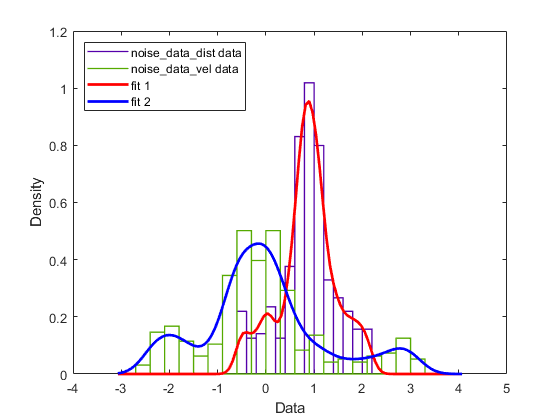

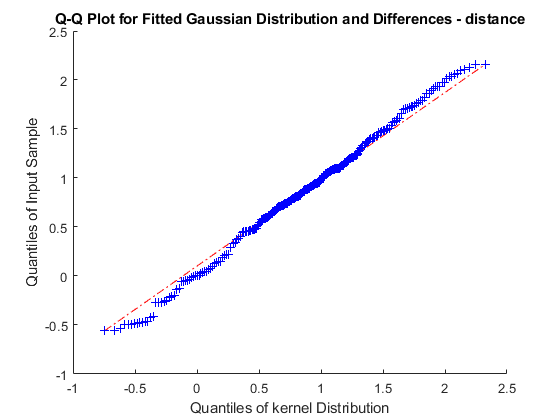

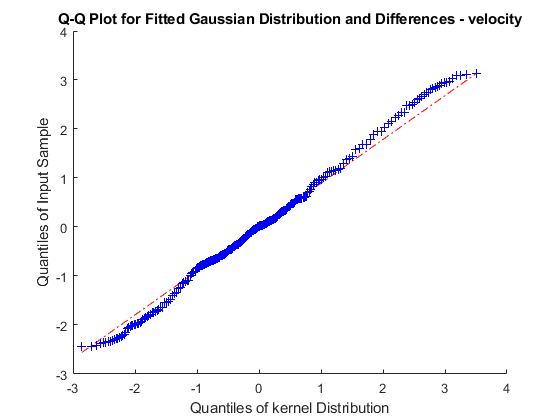

pd1 =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.136515
    Support = unbounded


pd2 =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.276088
    Support = unbounded


[pd1,pd2] = createFit(noise_data_dist,noise_data_vel)

After applyying non-parametric distribution, we are able to generate mixture of uniform distribution, which better maps underlying probalistic distribution of the noise. This is further confirmed by almost linear pattern in Q-Q plots. There are still some deviations near the tale but they are not as extreme as the normal distribution case. 

### Finding confidence bounds

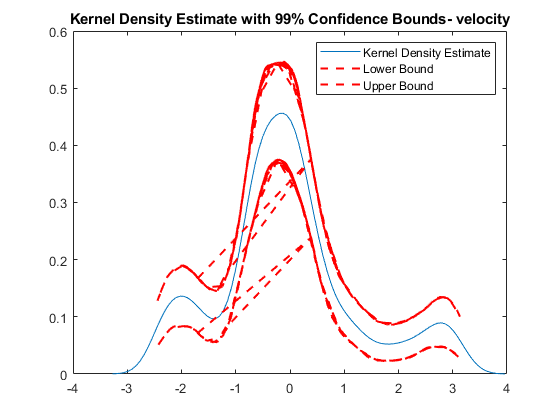

bootstrap_bounds(noise_data_vel, 'velocity')

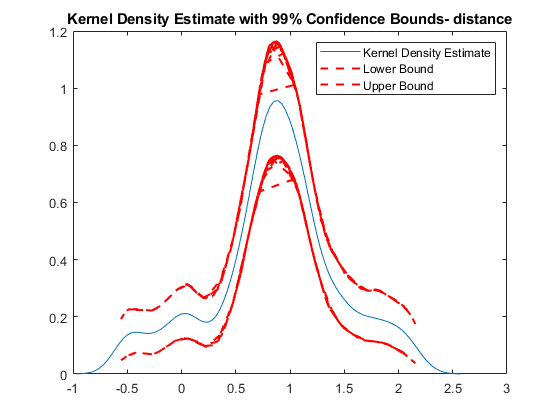

bootstrap_bounds(noise_data_dist, 'distance')

[l_v, u_v] = get_confidence_bound(noise_data_vel, 0.9999,'velocity');
[l_d, u_d] = get_confidence_bound(noise_data_dist, 0.9999, 'distance');

The noise bounds with 99.99% confidence intervals are  

relative velocity noise : -3.2706, 3.9604

relative distance noise: -0.96766, 2.5648

Now we can use these as our disturbance bounds to ensure the adaptive mpc is robust to these noises. 

NOTE:  that min, max values for 

vel (-2.4423, 3.1321)

dist (-0.5581, 2.1552)

So we are finding the underline probablility distribution and finding these confidence values, rather than picking minimum or maximum. This way we can have confidence bound around our robustness due to noise around our controller. This is to ensure the worst random noises have minimal effect on our system. This with in conjunction to safety filter, the controller should be safe for all distrubanes. However the statement needs to be mathematically proven. 

## DNN method to predict the noise based on 

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |         1.31 |          0.9 |          0.0010 |


|      50 |          50 |       00:00:20 |         0.78 |          0.3 |          0.0010 |


|========================================================================================|


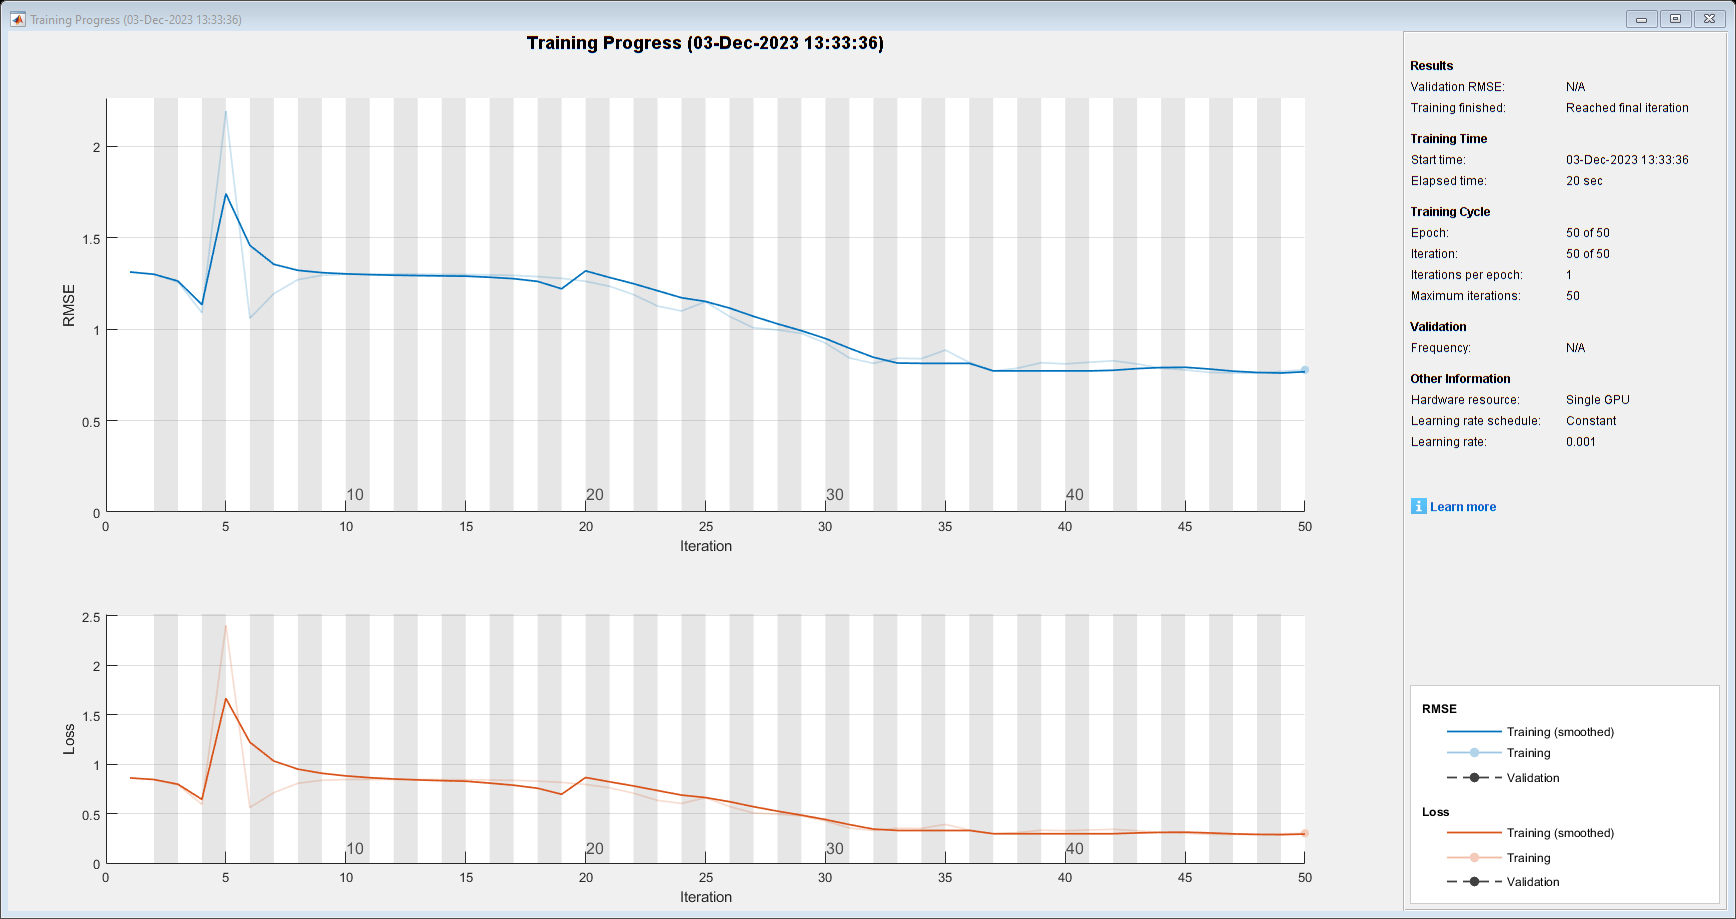

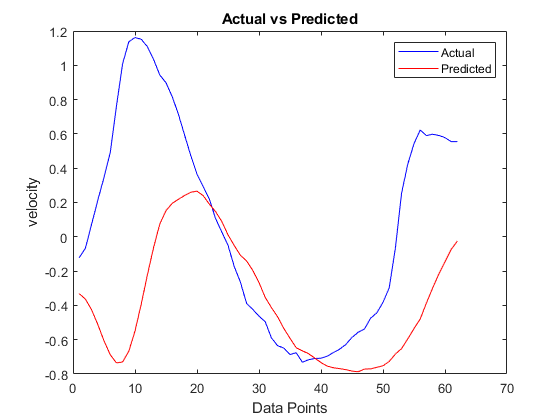

vel_net =   SeriesNetwork with properties:

         Layers: [14×1 nnet.cnn.layer.Layer]
     InputNames: {'Input'}
    OutputNames: {'routput'}


difference = ground_truth_rel_velocity - sensor_rel_velocity;
fitlered_sensor_rel_velocity = sensor_rel_velocity(isfinite(difference));
difference = ground_truth_rel_distance - sensor_rel_distance;
fitlered_sensor_rel_distance = sensor_rel_distance(isfinite(difference));

% using sliding window
window_size = 10; % Adjust window size as needed
vel_net = predict_noise(fitlered_sensor_rel_velocity, noise_data_vel, window_size, "velocity")

### No normalisation

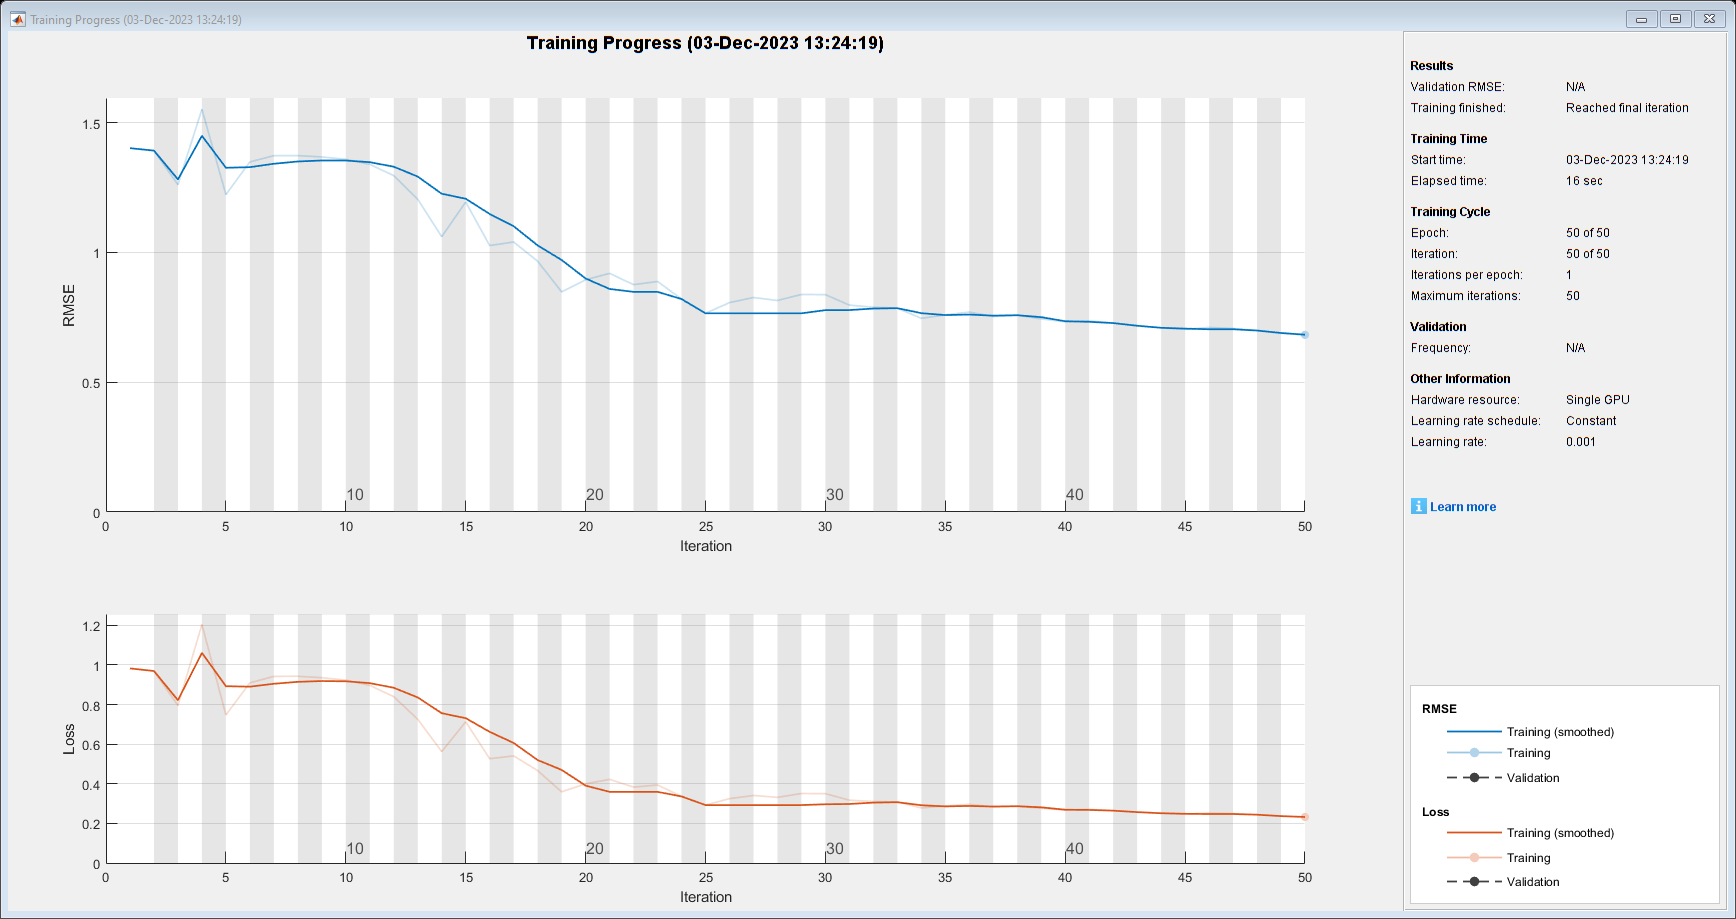

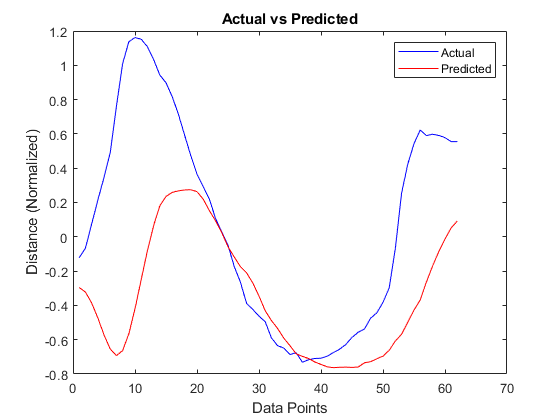

not great a predicting high errors

### with normalisation

the loss curves are similar fofor epochs >30

function net = predict_noise(sensor_data, ground_truth, window_size, type_string)
    % Define window size and stride
 
    stride = 1; % Adjust stride as needed
    
    
    % Generate sequences using sliding window
    [train_data, train_labels] = createSlidingWindowData(sensor_data, ground_truth, window_size, stride);
    
    train_labels =  cell2mat(train_labels);
    % Split data into training and testing sets (80% training, 20% testing)
    split_ratio = 0.8;
    split_idx = floor(split_ratio * size(train_data, 1));
    
    train_data_split = train_data(1:split_idx, :);
    train_labels_split = train_labels(1:split_idx, :);
    
    test_data_split = train_data(split_idx+1:end, :);
    test_labels_split = train_labels(split_idx+1:end, :);
    
    % Define network parameters
    numHiddenUnits = 512;
    dropoutRate = 0.1;
    % Create LSTM layers with dropout
    layers = [
        sequenceInputLayer(size(train_data_split{1}, 1), 'Name', 'Input', 'Normalization', 'zscore')
        lstmLayer(numHiddenUnits*4, 'OutputMode', 'sequence', 'Name', 'lstm1')
        dropoutLayer(dropoutRate, 'Name', 'dropout1')
         lstmLayer(numHiddenUnits*2, 'OutputMode', 'last', 'Name', 'lstm2')
        dropoutLayer(dropoutRate, 'Name', 'dropout2')
    %     lstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'lstm3')
    %     dropoutLayer(dropoutRate, 'Name', 'dropout3')
        lstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'lstm3')
        dropoutLayer(dropoutRate, 'Name', 'dropout3')
         lstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'lstm4')
        dropoutLayer(dropoutRate, 'Name', 'dropout4')
        fullyConnectedLayer(numHiddenUnits*4, 'Name', 'fc4')
        fullyConnectedLayer(numHiddenUnits*2, 'Name', 'fc3')
        fullyConnectedLayer(numHiddenUnits, 'Name', 'fc2')
        fullyConnectedLayer(1, 'Name', 'fc')
        regressionLayer('Name', 'routput')
    ];
    options = trainingOptions('adam', 'Plots', 'training-progress', 'MaxEpochs', 50);
          
    % Create a network object
    net = trainNetwork(train_data_split', train_labels_split, layers, options);
    
    % Predict using the trained network
    predicted_labels = predict(net, test_data_split');
    
    % Measure performance (e.g., Mean Squared Error)
    mse = mean((predicted_labels - test_labels_split').^2);
    
    % Visualize predictions versus actual values
    plot(test_labels_split', 'b');
    hold on;
    plot(predicted_labels, 'r');
    legend('Actual', 'Predicted');
    xlabel('Data Points');
    ylabel(type_string);
    title('Actual vs Predicted');
    hold off
end

function [input_sequences, output_sequences] = createSlidingWindowData(sensor_data, ground_truth, window_size, stride)
    num_samples = size(sensor_data, 1);
    % Preallocate cell arrays with expected size
    num_windows = floor((num_samples - window_size + 1) / stride);
    input_sequences = cell(num_windows, 1);
    output_sequences = cell(num_windows, 1);

    % Loop and assign directly using indexing
    for i = 1:stride:(num_samples - window_size + 1)
        input_sequences{i} = sensor_data(i:i+window_size-1, :);
        output_sequences{i} = ground_truth(i+window_size-1, :)';
    end
    
end



### Aux functions

fitler the data

function new_data = filter_data(data)
    new_data = data(isfinite(data));
end

q-q test function

function noise_data = perform_qq_test(ground_truth, sensor_data, type_string)
    % Assuming ground truth is 'ground_truth_data' and sensor data is 'sensor_data'
    difference = ground_truth - sensor_data;
    % Filter out infinite values
    difference = difference(isfinite(difference));
    % Plotting histogram of the differences
    figure;
    histogram(difference);
    title(['Histogram of Differences (Noise) - ', type_string]); % Include type_string in the title
    
    % Fit Gaussian distribution to the differences
    pd_noise = fitdist(difference, 'Normal');
    disp('Parameters of fitted Gaussian distribution for noise:');
    disp(pd_noise);
    % Q-Q plot for the fitted Gaussian distribution and differences
    figure;
    qqplot(difference, pd_noise);
    title(['Q-Q Plot for Fitted Gaussian Distribution and Differences - ', type_string]); % Include type_string in the title
    noise_data = difference;
end

Shapiro-Wilk test function 

function [h, p, w] = shapiro_wilk_test(data, type_string)
    % Perform Shapiro-Wilk test
    [h, p, w] = swtest(data);
    
    % Display test results
    disp(['Shapiro-Wilk Test - ', type_string]);
    if h == 0
        disp('The data appears to be normally distributed (Failed to reject H0).');
    else
        disp('The data does not appear to be normally distributed (Rejected H0).');
    end
    disp(['p-value: ', num2str(p)]);
    disp(['Test statistic (W): ', num2str(w)]);
end

general fitting

function [pd1,pd2] = createFit(noise_data_dist,noise_data_vel)
%CREATEFIT    Create plot of datasets and fits
%   [PD1,PD2] = CREATEFIT(NOISE_DATA_DIST,NOISE_DATA_VEL)
%   Creates a plot, similar to the plot in the main distribution fitter
%   window, using the data that you provide as input.  You can
%   apply this function to the same data you used with dfittool
%   or with different data.  You may want to edit the function to
%   customize the code and this help message.
%
%   Number of datasets:  2
%   Number of fits:  2
%
%   See also FITDIST.

% This function was automatically generated on 03-Dec-2023 02:08:01

% Output fitted probablility distributions: PD1,PD2

% Data from dataset "noise_data_dist data":
%    Y = noise_data_dist

% Data from dataset "noise_data_vel data":
%    Y = noise_data_vel

% Force all inputs to be column vectors
noise_data_dist = noise_data_dist(:);
noise_data_vel = noise_data_vel(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "noise_data_dist data"
[CdfF,CdfX] = ecdf(noise_data_dist,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(noise_data_dist,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'noise_data_dist data';

% --- Plot data originally in dataset "noise_data_vel data"
[CdfF,CdfX] = ecdf(noise_data_vel,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(noise_data_vel,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0.666667 0],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'noise_data_vel data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "fit 1"
pd1 = fitdist(noise_data_dist,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';

% --- Create fit "fit 2"
pd2 = fitdist(noise_data_vel,'kernel','kernel','normal','support','unbounded');
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northwest');
set(hLegend,'Interpreter','none');
figure
qqplot(noise_data_dist, pd1);
title('Q-Q Plot for Fitted Gaussian Distribution and Differences - distance');
figure
qqplot(noise_data_vel, pd2);
title('Q-Q Plot for Fitted Gaussian Distribution and Differences - velocity');
end



function [pd1,pd2] = create_quantile_plots(noise_data_dist,noise_data_vel)
%CREATEFIT    Create plot of datasets and fits
%   [PD1,PD2] = CREATE_QUANTILE_PLOTS(NOISE_DATA_DIST,NOISE_DATA_VEL)
%   Creates a plot, similar to the plot in the main distribution fitter
%   window, using the data that you provide as input.  You can
%   apply this function to the same data you used with dfittool
%   or with different data.  You may want to edit the function to
%   customize the code and this help message.
%
%   Number of datasets:  2
%   Number of fits:  2
%
%   See also FITDIST.

% This function was automatically generated on 03-Dec-2023 02:41:44

% Output fitted probablility distributions: PD1,PD2

% Data from dataset "noise_data_dist data":
%    Y = noise_data_dist

% Data from dataset "noise_data_vel data":
%    Y = noise_data_vel

% Force all inputs to be column vectors
noise_data_dist = noise_data_dist(:);
noise_data_vel = noise_data_vel(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "noise_data_dist data"
[CdfY,CdfX] = ecdf(noise_data_dist,'Function','cdf');  % compute empirical cdf
hLine = stairs(CdfY,[CdfX(2:end);CdfX(end)],'Color',[0.333333 0 0.666667],'LineStyle','-', 'LineWidth',1);
xlabel('Probability');
ylabel('Quantile')
LegHandles(end+1) = hLine;
LegText{end+1} = 'noise_data_dist data';

% --- Plot data originally in dataset "noise_data_vel data"
[CdfY,CdfX] = ecdf(noise_data_vel,'Function','cdf');  % compute empirical cdf
hLine = stairs(CdfY,[CdfX(2:end);CdfX(end)],'Color',[0.333333 0.666667 0],'LineStyle','-', 'LineWidth',1);
xlabel('Probability');
ylabel('Quantile')
LegHandles(end+1) = hLine;
LegText{end+1} = 'noise_data_vel data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "fit 1"
pd1 = fitdist(noise_data_dist,'kernel','kernel','normal','support','unbounded');
YPlot = icdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';

% --- Create fit "fit 2"
pd2 = fitdist(noise_data_vel,'kernel','kernel','normal','support','unbounded');
YPlot = icdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
end

function bootstrap_bounds(data, type_string)
    % Number of bootstrap samples
    num_bootstraps = 1000;
    
    % Preallocate array for kernel density estimates
    kernel_estimates = zeros(num_bootstraps, length(data));
    
    % Generating bootstrap samples and calculating kernel density estimates
    for i = 1:num_bootstraps
        % Resampling from the data with replacement
        bootstrap_sample = datasample(data, length(data));
        
        % Fitting a kernel distribution to each bootstrap sample
        pd_bootstrap = fitdist(bootstrap_sample, 'Kernel', 'Kernel', 'Normal');
        kernel_estimates(i, :) = pdf(pd_bootstrap, data); % Use pdf() to get density estimates
    end
    
    % Calculating confidence intervals (e.g., 99% confidence bounds)
    alpha = 0.01; % significance level
    lower_bound = prctile(kernel_estimates, alpha/2 * 100); % lower bound
    upper_bound = prctile(kernel_estimates, (1 - alpha/2) * 100); % upper bound
    
    % Plotting the original kernel density estimate and confidence bounds
    figure;
    ksdensity(data); % Plot the original kernel density estimate
    hold on;
    plot(data, lower_bound, 'r--', 'LineWidth', 1.5); % Plot lower bound
    plot(data, upper_bound, 'r--', 'LineWidth', 1.5); % Plot upper bound
    hold off;
    title(['Kernel Density Estimate with 99% Confidence Bounds- ', type_string]);
    legend('Kernel Density Estimate', 'Lower Bound', 'Upper Bound');
end

function [l, u] = get_confidence_bound(data, confidence, type_string)
    l = min(data);
    u = max(data);
    % Calculating kernel density estimate
    [f, xi] = ksdensity(data);
    
    % Calculate the cumulative distribution function (CDF)
    cdf_values = cumtrapz(xi, f);
    
    [c_indices_lower, c_indices_upper] = get_confidence_bound_indices(cdf_values, confidence);
    
    if ~isempty(c_indices_lower) && ~isempty(c_indices_upper) 
        c_lower = xi(c_indices_lower); % Get the corresponding value of 'c'
        c_upper = xi(c_indices_upper);
        l = c_lower;
        u = c_upper;
        disp([type_string,' - Value of c where CDF is outside the bound: (', num2str(c_lower), ', ',  num2str(c_upper), ')']);
    else
        disp([type_string, ' - No value of c found where CDF >', confidence]);
    end
end

function [c_indices_lower, c_indices_upper] = get_confidence_bound_indices(cdf_values, confidence)
    % Find the value of 'c' when CDF > 0.99
    c_indices_upper = find(cdf_values > confidence, 1); % Find the first index where CDF > 0.99
    c_indices_lower = find(cdf_values < 1-confidence, 1); % Find the first index where CDF < 1- 0.99
end